%скрипт для извлечения данных и создание датасета для обучения нейросети для ГРС
clear
d = dir('C:\Users\user\MATLAB Drive\1Exponenta\data good\data_4_GRS');
d(1:3) = [];
t = [];

for i = 1:numel(d) 
    disp(i) % демо считывания данных по месяцам
    str = d(i).folder +"\"+ d(i).name; % считываем имя файла в директории d
    a = readfile_all(str); % читаем файл, к которому обращаемся
    t = [t;a]; % считываем каждый файл и конкатенируем с предыдущим
    % t - содержит все ненормированные данные по 12 месяца по 4 ГРС
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12



t(:,end-1) = [];
Q_grs_total = t(:,end);% удаляем последнюю колонку, там сумма по ГРС
save data_grs_total Q_grs_total

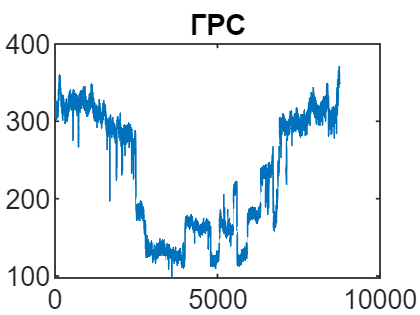

figure
plot(Q_grs_total);
title("ГРС");

Q_gis = readtable('GIS_no_interp.xlsx');
Q_gis = table2array(Q_gis);

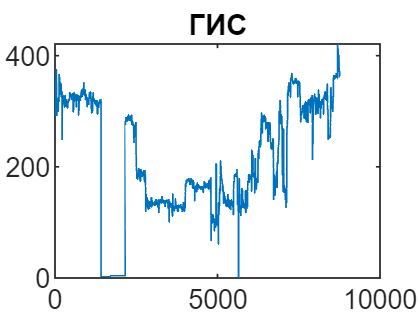

% Q_gis = t1(:,9);
plot(Q_gis);
title("ГИС");

% save dataGIS_total t1

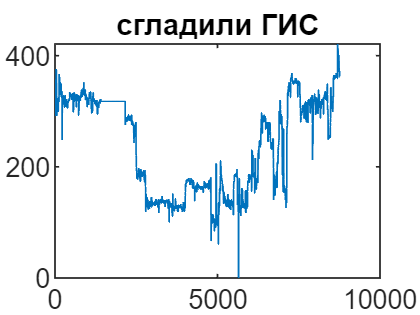

% сгладили ГИС
figure
Q_gis_1 = readtable('GIS_with_interp.xlsx');
Q_gis_1 = table2array(Q_gis_1);
plot(Q_gis_1);
title("сгладили ГИС");

save dataGIS_total Q_gis_1

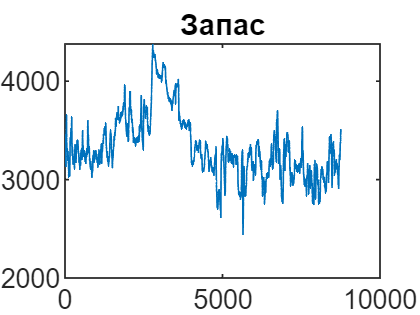

Z = readtable('Zapas_data_with_marth.xlsx');
ind = 1:size(Z,1) * 2;
ind_z = 2:2:size(Z,1) * 2;
Z_1 = Z.Var2;
Z_2 = Z.Var3;
Z_3 = Z.Var4;
z_interp_1 = interp1(ind_z,Z_1,ind,"spline");
z_interp_2 = interp1(ind_z,Z_2,ind,"spline");
z_interp_3 = interp1(ind_z,Z_3,ind,"spline");
Zapas = z_interp_3/1000;
figure
plot(z_interp_3);
title("Запас");

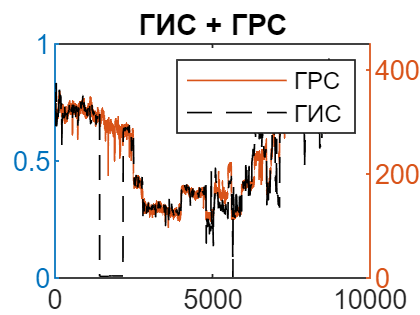

figure
yyaxis right
plot(Q_grs_total);
yyaxis right
hold on
plot(Q_gis, "k");
title("ГИС + ГРС");
legend ("ГРС", "ГИС");

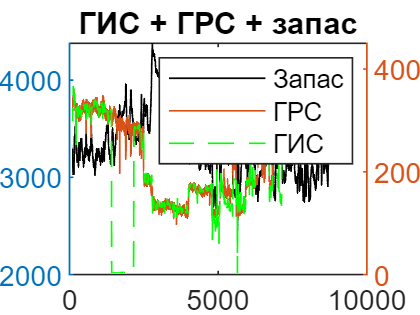

figure
yyaxis right
plot(Q_grs_total);
yyaxis right
hold on
plot(Q_gis, "g");
hold on
yyaxis left
plot(z_interp_3, "k");
title("ГИС + ГРС + запас");
legend ("Запас", "ГРС", "ГИС");

Balance_1 = Q_gis - Q_grs_total; % не сгладили ГИС
Balance_2 = Q_gis(3:8760, :) - Q_grs_total(3:8760, :) - Zapas'; % не сгладили ГИС

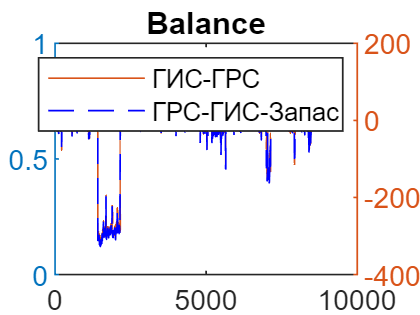

figure
yyaxis right
plot(Balance_1);
yyaxis right
hold on
plot(Balance_2, "b");
title("Balance");
legend ("ГИС-ГРС", "ГРС-ГИС-Запас");

Year_balance_gis_grs = sum(Balance_1); % не сгладили ГИС
Year_balance = sum(Balance_2); % не сгладили ГИС

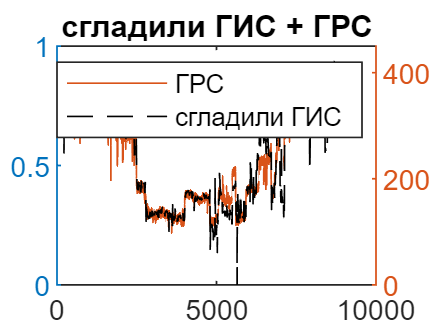

figure
yyaxis right
plot(Q_grs_total);
yyaxis right
hold on
plot(Q_gis_1, "k");
title("сгладили ГИС + ГРС");
legend ("ГРС", "сгладили ГИС");

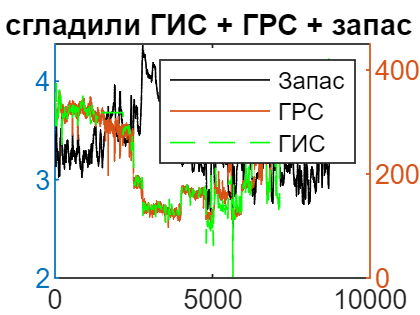

figure
yyaxis right
plot(Q_grs_total);
yyaxis right
hold on
plot(Q_gis_1, "g");
hold on
yyaxis left
plot(Zapas, "k");
title("сгладили ГИС + ГРС + запас ");
legend ("Запас", "ГРС", "ГИС");

Balance_1_1 = Q_gis_1(1:8758, :) - Q_grs_total(1:8758, :); % сгладили ГИС
Balance_2_1 = Q_gis_1(1:8758, :) - Q_grs_total(1:8758, :) - Zapas'; % сгладили ГИС

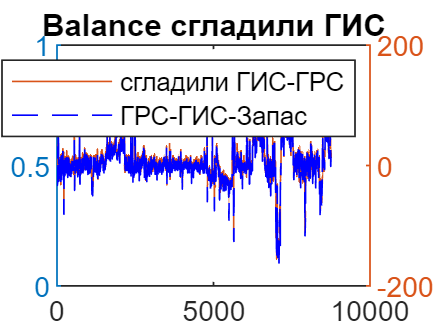

figure
yyaxis right
plot(Balance_1_1);
yyaxis right
hold on
plot(Balance_2_1, "b");
title("Balance сгладили ГИС");
legend ("сгладили ГИС-ГРС", "ГРС-ГИС-Запас");

Year_balance_1 = sum(Balance_2_1); % сгладили ГИС
Delta_gis = Year_balance_1 - Year_balance; % разница если не сгладили и сгладили ГИС

sum_grs = sum(Q_grs_total(1:8758, :));
sum_gis = sum(Q_gis(1:8758, :));
sum_gis_1 = sum(Q_gis_1(1:8758, :));
delta_gis = sum_gis - sum_gis_1;
sum_zapas = sum(Zapas);

Year_balance_from_sum = sum(Q_grs_total(1:8758, :)) - sum(Q_gis(1:8758, :)) - sum(Zapas) ;
Year_balance_from_sum_1 = sum(Q_grs_total(1:8758, :)) - sum(Q_gis_1(1:8758, :)) - sum(Zapas) ;
Delta_gis_from_sum = Year_balance_from_sum_1 - Year_balance_from_sum;

figure
yyaxis right
plot(Q_grs_total, "k");
yyaxis right
hold on
plot(Q_gis_1, "g");
yyaxis left
hold on
plot(Zapas, "r");
title("сгладили ГИС + ГРС + запас ");
legend ("Запас",  "ГРС", "ГИС");

function t = readfile_all(str)
[t,txt] = xlsread(str,'ГРС');
%%
s = all(isnan(t));
t(:,s) = [];
b = all(isnan(t),2);
t(b,:) = [];
end